# Support Vector Machine vs. Random Forest Classifier Evaluation

Đánh giá và so sánh mô hình SVM (RBF Kernel) và Random Forest trên bộ đặc trưng dung hợp (Hình thái + Màu sắc HSV + Kết cấu GLCM).

## 1. Thiết lập Đường dẫn & Tải kết quả

clear; clc; close all;

% Định vị đường dẫn chạy công cụ bằng cách tìm thư mục gốc chứa 'reports' và 'src'
current_search_dir = pwd;
try
    mfile_path = fileparts(mfilename('fullpath'));
    if ~isempty(mfile_path)
        current_search_dir = mfile_path;
    end
catch
end

project_root = '';
for level = 1:5
    if exist(fullfile(current_search_dir, 'reports'), 'dir') && exist(fullfile(current_search_dir, 'src'), 'dir')
        project_root = current_search_dir;
        break;
    end
    parent_dir = fileparts(current_search_dir);
    if strcmp(parent_dir, current_search_dir)
        break;
    end
    current_search_dir = parent_dir;
end

if isempty(project_root)
    project_root = pwd;
end

reports_dir = fullfile(project_root, 'reports');
src_dir = fullfile(project_root, 'src');
results_path = fullfile(reports_dir, 'svm_rf_results.mat');

% Nếu chưa chạy huấn luyện, tự động gọi file train_svm_rf.m
if ~exist(results_path, 'file')
    fprintf('Chưa tìm thấy kết quả SVM & RF. Đang huấn luyện...\n');
    run(fullfile(src_dir, 'train_svm_rf.m'));
end

% Load kết quả
load(results_path);

## 2. So sánh hiệu năng tổng quát giữa SVM và Random Forest

PerformanceTable = table(model_names', accuracies', f1_scores', ...
    'VariableNames', {'Model', 'Accuracy', 'Macro_F1_Score'});
disp('Bảng hiệu năng tổng quát của SVM và Random Forest:');

Bảng hiệu năng tổng quát của SVM và Random Forest:


disp(PerformanceTable);

          Model          Accuracy    Macro_F1_Score
    _________________    ________    ______________

    {'SVM (RBF)'    }    0.47638        0.41706    
    {'Random Forest'}    0.62685        0.51827    



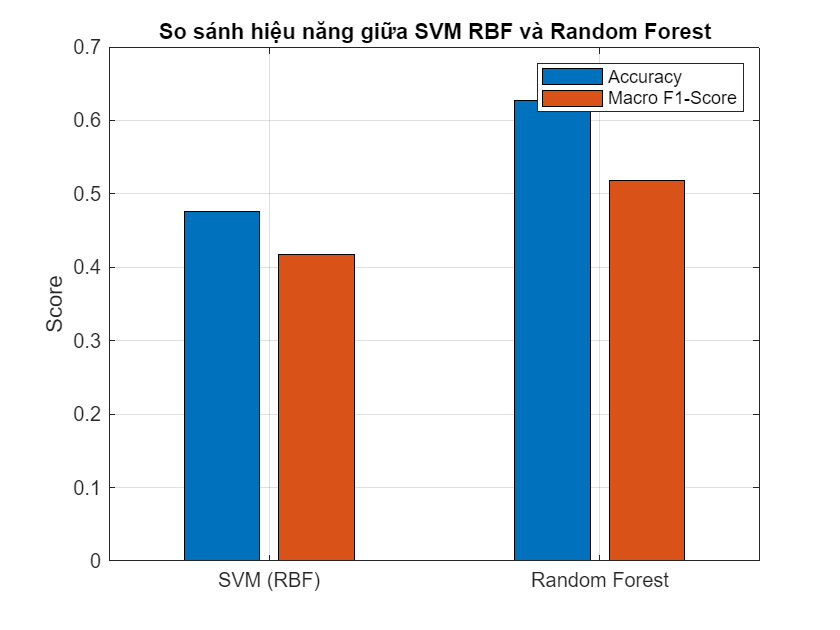


% Vẽ biểu đồ so sánh F1-score và Accuracy
figure('Name', 'SVM vs RF Comparison');
bar([accuracies; f1_scores]');
set(gca, 'XTickLabel', model_names);
ylabel('Score');
legend({'Accuracy', 'Macro F1-Score'}, 'Location', 'northeast');
title('So sánh hiệu năng giữa SVM RBF và Random Forest');
grid on;

% Lưu đồ thị so sánh
saveas(gcf, fullfile(reports_dir, 'svm_rf_comparison.png'));

## 3. Đánh giá chi tiết mô hình SVM (RBF)

C_svm = confusionmat(Y_test, predictions{1});
class_names = unique(string(Y_test));
num_classes = numel(class_names);

precisions_svm = zeros(num_classes, 1);
recalls_svm = zeros(num_classes, 1);
f1s_svm = zeros(num_classes, 1);

for c = 1:num_classes
    tp = C_svm(c, c);
    fp = sum(C_svm(:, c)) - tp;
    fn = sum(C_svm(c, :)) - tp;
    
    if (tp + fp) > 0, precisions_svm(c) = tp / (tp + fp); else, precisions_svm(c) = 0; end
    if (tp + fn) > 0, recalls_svm(c) = tp / (tp + fn); else, recalls_svm(c) = 0; end
    if (precisions_svm(c) + recalls_svm(c)) > 0
        f1s_svm(c) = 2 * (precisions_svm(c) * recalls_svm(c)) / (precisions_svm(c) + recalls_svm(c));
    else
        f1s_svm(c) = 0;
    end
end

SVM_ClassTable = table(class_names, precisions_svm, recalls_svm, f1s_svm, ...
    'VariableNames', {'Class_Name', 'Precision', 'Recall', 'F1_Score'});
disp('Bảng chi tiết chỉ số đo lường của mô hình SVM (RBF):');

Bảng chi tiết chỉ số đo lường của mô hình SVM (RBF):


disp(SVM_ClassTable);

                     Class_Name                      Precision     Recall     F1_Score
    _____________________________________________    _________    ________    ________

    "Pepper__bell___Bacterial_spot"                         1      0.18593    0.31356 
    "Pepper__bell___healthy"                          0.86813      0.53559    0.66247 
    "Potato___Early_blight"                           0.91667        0.495    0.64286 
    "Potato___Late_blight"                            0.77778      0.10448    0.18421 
    "Potato___healthy"                                      1     0.066667      0.125 
    "Tomato_Bacterial_spot"                           0.95385      0.58353    0.72409 
    "Tomato_Early_blight"                             0.73333     0.054726    0.10185 
    "Tomato_Late_blight"                              0.47727      0.38482    0.

## 4. Đánh giá chi tiết mô hình Random Forest

C_rf = confusionmat(Y_test, predictions{2});

precisions_rf = zeros(num_classes, 1);
recalls_rf = zeros(num_classes, 1);
f1s_rf = zeros(num_classes, 1);

for c = 1:num_classes
    tp = C_rf(c, c);
    fp = sum(C_rf(:, c)) - tp;
    fn = sum(C_rf(c, :)) - tp;
    
    if (tp + fp) > 0, precisions_rf(c) = tp / (tp + fp); else, precisions_rf(c) = 0; end
    if (tp + fn) > 0, recalls_rf(c) = tp / (tp + fn); else, recalls_rf(c) = 0; end
    if (precisions_rf(c) + recalls_rf(c)) > 0
        f1s_rf(c) = 2 * (precisions_rf(c) * recalls_rf(c)) / (precisions_rf(c) + recalls_rf(c));
    else
        f1s_rf(c) = 0;
    end
end

RF_ClassTable = table(class_names, precisions_rf, recalls_rf, f1s_rf, ...
    'VariableNames', {'Class_Name', 'Precision', 'Recall', 'F1_Score'});
disp('Bảng chi tiết chỉ số đo lường của mô hình Random Forest:');

Bảng chi tiết chỉ số đo lường của mô hình Random Forest:


disp(RF_ClassTable);

                     Class_Name                      Precision    Recall     F1_Score
    _____________________________________________    _________    _______    ________

    "Pepper__bell___Bacterial_spot"                   0.69697     0.46231    0.55589 
    "Pepper__bell___healthy"                           0.6026     0.78644    0.68235 
    "Potato___Early_blight"                           0.61837       0.875    0.72464 
    "Potato___Late_blight"                             0.6087     0.20896    0.31111 
    "Potato___healthy"                                      0           0          0 
    "Tomato_Bacterial_spot"                           0.81746     0.72706    0.76961 
    "Tomato_Early_blight"                              0.4902     0.12438    0.19841 
    "Tomato_Late_blight"                              0.56461     0.52618    0.54472 
   

## 5. Trực quan hóa Ma trận Nhầm lẫn (Confusion Matrix)

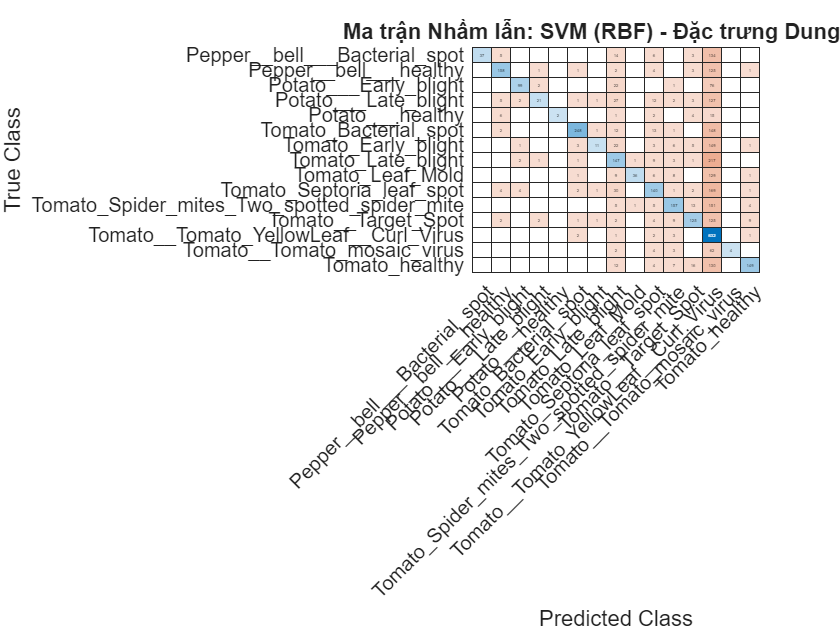

figure('Name', 'Confusion Matrix - SVM');
cm_svm_plot = confusionchart(Y_test, predictions{1});
cm_svm_plot.Title = 'Ma trận Nhầm lẫn: SVM (RBF) - Đặc trưng Dung hợp';

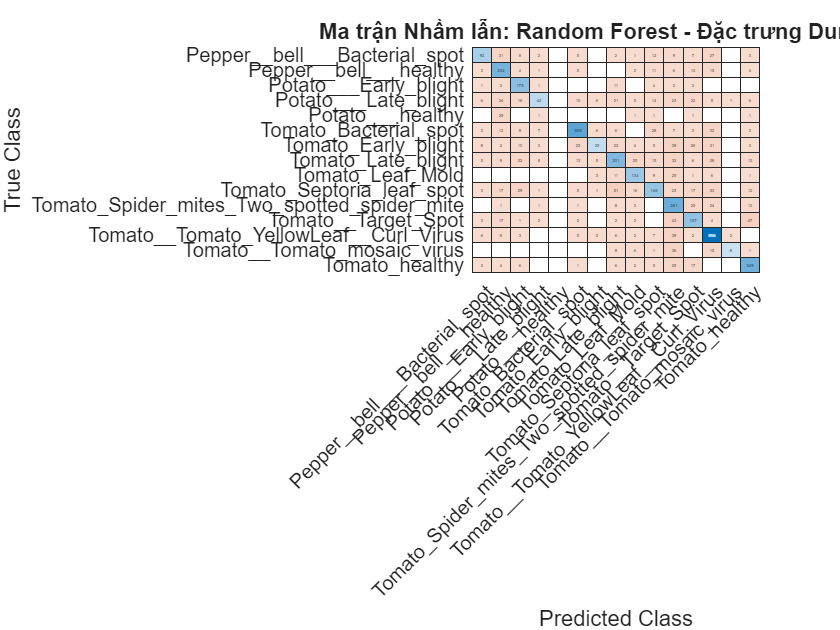


figure('Name', 'Confusion Matrix - Random Forest');
cm_rf_plot = confusionchart(Y_test, predictions{2});
cm_rf_plot.Title = 'Ma trận Nhầm lẫn: Random Forest - Đặc trưng Dung hợp';

## 6. Phân tích Tường minh và So sánh (Explainability & Computational Costs)

1. ***Khả năng giải thích (Interpretability/Explainability)****: - Cả hai mô hình đều hoạt động trên bộ đặc trưng dung hợp tường minh (Diện tích lá, chu vi, tỉ lệ màu HSV, độ nhám GLCM) nên có độ giải thích rất cao so với "hộp đen" Deep Learning. - **Random Forest**** cung cấp tính năng xếp hạng mức độ quan trọng của đặc trưng (Feature Importance), cho biết thuộc tính nào (ví dụ: `H_Mean` - màu sắc vết bệnh, hay `Solidity` - độ lồi của lá) đóng góp nhiều nhất vào phân lớp bệnh. - **SVM (RBF)*** xây dựng ranh giới quyết định phi tuyến tính (non-linear boundary) bằng cách chiếu dữ liệu lên không gian nhiều chiều thông qua các điểm hỗ trợ (Support Vectors) là các lá cây biên điển hình.

2. ***Chi phí tính toán (Computational Cost)****: - SVM RBF huấn luyện mất ***~9 giây** và Random Forest mất ~2.5 giây** trên CPU cho 16,511 mẫu huấn luyện. - Quá trình huấn luyện cực kỳ nhanh so với việc chạy tích chập và lan truyền ngược của Deep Learning, đồng thời việc lưu trữ mô hình cũng vô cùng nhẹ (chỉ vài MB).